# Lab 5

Gabriel Casciano, 500744076

## Part A

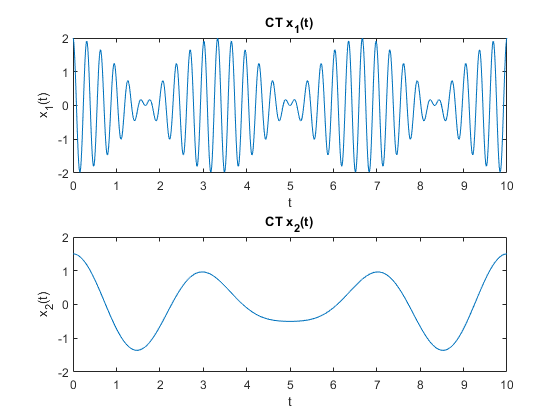

x_1 = @(n) exp(j*2*pi*30/10 .* n) + exp(j*2*pi*33/10 .* n);
x_2 = @(n) cos(2*pi*30/100 .* n) + .5*cos(2*pi*40/100 .* n);

n = 0:.01:10;

x1 = x_1(n);
x2 = x_2(n);

subplot(2,1,1);
plot(n, real(x1));
title("CT x_{1}(t)");
xlabel("t");
ylabel("x_{1}(t)");

subplot(2,1,2);
plot(n, x2);
title("CT x_{2}(t)");
xlabel("t");
ylabel("x_{2}(t)");

### A1

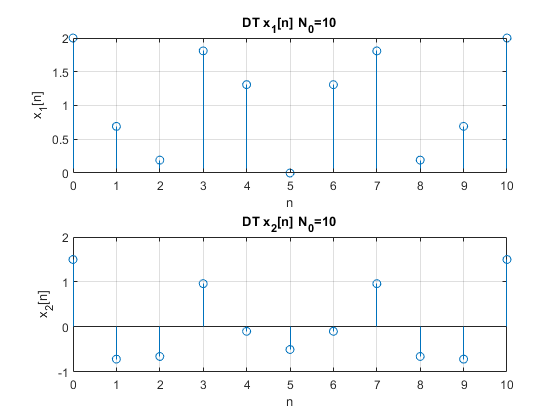

N  = 10;
n = 0:N;

x1 = x_1(n);
x2 = x_2(n);

subplot(2,1,1);
stem(n, real(x1));
title("DT x_{1}[n] N_{0}=10");
xlabel("n");
ylabel("x_{1}[n]");
grid on;

subplot(2,1,2);
stem(n, x2);
title("DT x_{2}[n] N_{0}=10");
xlabel("n");
ylabel("x_{2}[n]");
grid on;

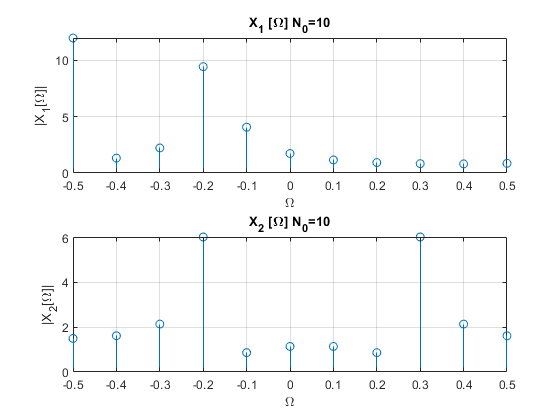

X1 = fft(x1);
X2 = fft(x2);

fr = -1/2:1/N:1/2;

subplot(2,1,1);
stem(fr, abs(X1));
title("X_{1} [\Omega] N_{0}=10");
xlabel("\Omega");
ylabel("|X_{1}[\Omega]|");
grid on;

subplot(2,1,2);
stem(fr, abs(X2));
title("X_{2} [\Omega] N_{0}=10");
xlabel("\Omega");
ylabel("|X_{2}[\Omega]|");
grid on;

#### i)

Spectrum $X_2
$ is symmetric, but I fear that because if the low $N_0
$ the signal is not being properly sampled and thus is not very visisble. $X_1$ is clearly not symmetric

#### ii)

No, upon comparison with the graphs in part A2, you can not see all of the frequency components of $X_1
$ or $X_2$ but you can see most of them.

#### iii)

I am unsure what components am supposed to see, there are only 2 components which would be normal for $x_1[n]$ because the equation only has 2 sinusoids.

### A2

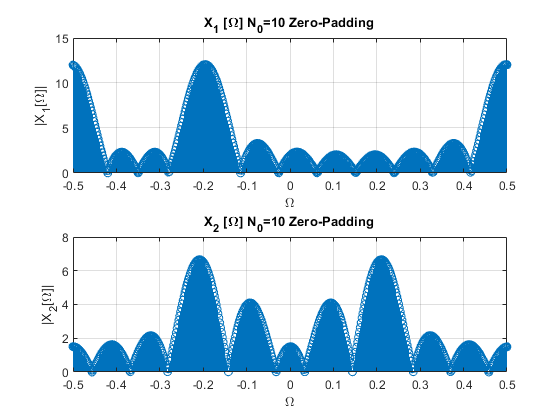

N = 500;
x1 = [x_1(n), zeros(1,N-10)];
x2 = [x_2(n), zeros(1,N-10)];

X1 = fft(x1);
X2 = fft(x2);

fr = -1/2:1/N:1/2;

subplot(2,1,1);
stem(fr, abs(X1));
title("X_{1} [\Omega] N_{0}=10 Zero-Padding");
xlabel("\Omega");
ylabel("|X_{1}[\Omega]|");
grid on;

subplot(2,1,2);
stem(fr, abs(X2));
title("X_{2} [\Omega] N_{0}=10 Zero-Padding");
xlabel("\Omega");
ylabel("|X_{2}[\Omega]|");
grid on;

There is a significant improvement in the resolution of the fft, however, zero-padding does not improve accuracy, it just allows us to better see what components we have.

### A3

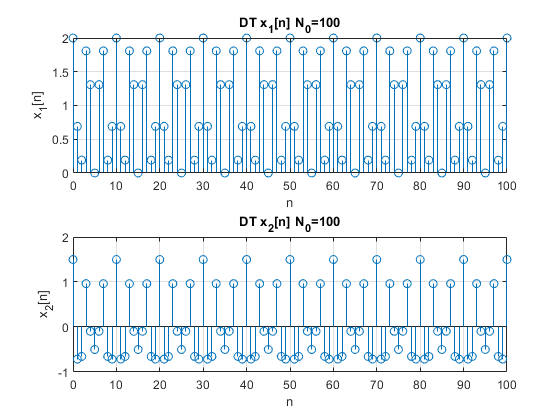

N  = 100;
n = 0:N;

x1 = x_1(n);
x2 = x_2(n);

subplot(2,1,1);
stem(n, real(x1));
title("DT x_{1}[n] N_{0}=100");
xlabel("n");
ylabel("x_{1}[n]");
grid on;

subplot(2,1,2);
stem(n, x2);
title("DT x_{2}[n] N_{0}=100");
xlabel("n");
ylabel("x_{2}[n]");
grid on;

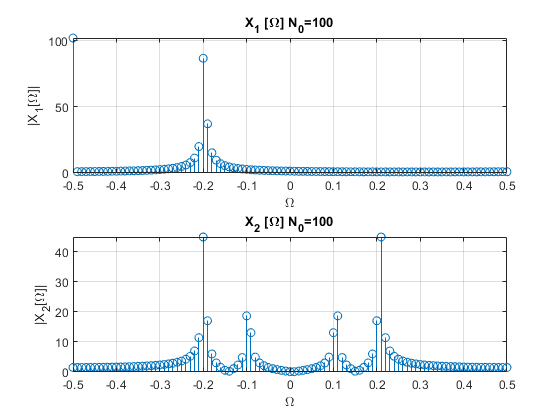

X1 = fft(x1);
X2 = fft(x2);

fr = -1/2:1/N:1/2;


subplot(2,1,1);
stem(fr, abs(X1));
title("X_{1} [\Omega] N_{0}=100");
xlabel("\Omega");
ylabel("|X_{1}[\Omega]|");
grid on;

subplot(2,1,2);
stem(fr, abs(X2));
title("X_{2} [\Omega] N_{0}=100");
xlabel("\Omega");
ylabel("|X_{2}[\Omega]|");
grid on;

Signal $x_2[n]$ has a symmetric signal, and that is the result of it not being over modulated, both signals are modulated signals, but for $x_1$ the modulating signal is too great thus over modulating and creating unwated spectral components. $x_2$ however is not over modulated resulting in a symmetric spectrum.

### A4

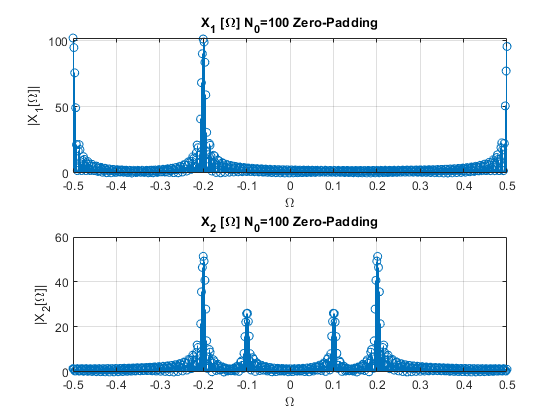

N = 500;
n = 0:100;
x1 = [x_1(n), zeros(1,N-100)];
x2 = [x_2(n), zeros(1,N-100)];

X1 = fft(x1);
X2 = fft(x2);

fr = -1/2:1/N:1/2;

subplot(2,1,1);
stem(fr, abs(X1));
title("X_{1} [\Omega] N_{0}=100 Zero-Padding");
xlabel("\Omega");
ylabel("|X_{1}[\Omega]|");
grid on;

subplot(2,1,2);
stem(fr, abs(X2));
title("X_{2} [\Omega] N_{0}=100 Zero-Padding");
xlabel("\Omega");
ylabel("|X_{2}[\Omega]|");
grid on;

Yes, relative to both the non zero padded, and to the lesser sampled signal. Relative to the non zero padded the spectrum is of higher resolution, naturally, and relative to the lesser sampled, we can see the peaks of our spectral components are more accurately defined, and are not as "bulbus" as $N_0=10$.

## Part B

T0 = 1; % duration
T = 1; % sampling
N0 = T0/T; % numbers of samples

### B1

load chirp.mat
filename = 'chirp.wav';
audiowrite(filename, y, Fs);
clear y Fs;

[y, Fs] = audioread('chirp.wav');

N0 = length(y)

N0 = 13129


T = (2*pi)/N0

T = 4.7857e-04

T0 = N0 * T

T0 = 6.2832

### B2

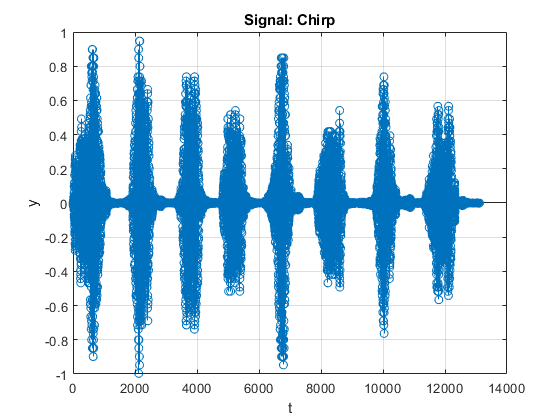

subplot(1,1,1);
stem(y);
title("Signal: Chirp");
ylabel("y");
xlabel("t");
grid on;

### B3

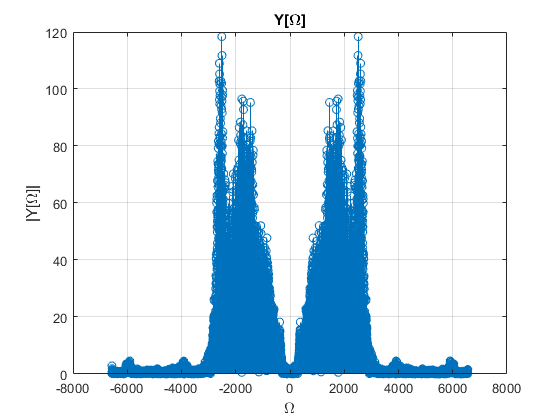

Y = fft(y);
fr = -((N0)/2):((N0-1)/2);

subplot(1,1,1);
stem(fr, abs(Y));
title("Y[\Omega]");
xlabel("\Omega");
ylabel("|Y[\Omega]|");
grid on;

### B4

n = 1:2:length(y);

N0 = length(n)

N0 = 6565

T = (2*pi)/N0

T = 9.5707e-04

T0 = N0 * T

T0 = 6.2832

y1 = y(n);

### B5

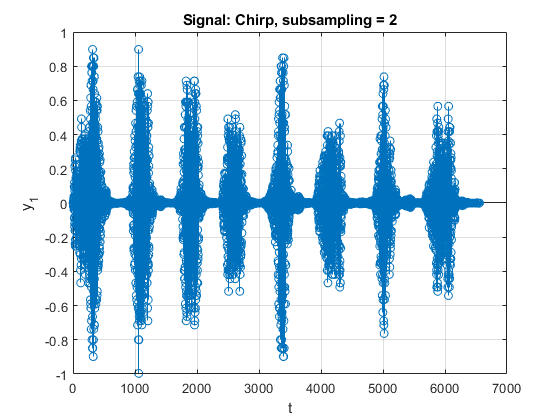

subplot(1,1,1);
stem(y1);
title("Signal: Chirp, subsampling = 2");
ylabel("y_1");
xlabel("t");
grid on;

### B6

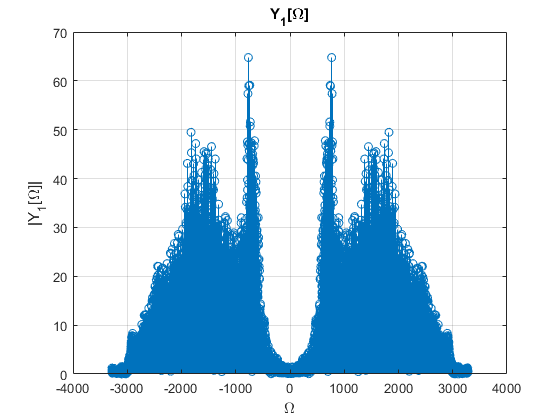

Y1 = fft(y1);

fr = -((N0)/2):((N0-1)/2);

subplot(1,1,1);
stem(fr, abs(Y1));
title("Y_1[\Omega]");
xlabel("\Omega");
ylabel("|Y_1[\Omega]|");
grid on;

If you compare the plots of $Y$ and $Y_1$ you can see that some of the higher frequency components have less magnitude now. As the result of downsampling, the samples are producing higher frequency sound less often so we hear a low pitch sound, and this is evident in the spectrum, as some of the higher frequency components have a reduced magnitude now.

### B7

There is an audible difference, the higher pitch sounds are still there just not as strong, and it almost sounds "flat" like entire signal has a lower overal pitch.

### B8

n = 1:5:length(y);

N0 = length(n)

N0 = 2626

T = (2*pi)/N0

T = 0.0024

T0 = N0 * T

T0 = 6.2832

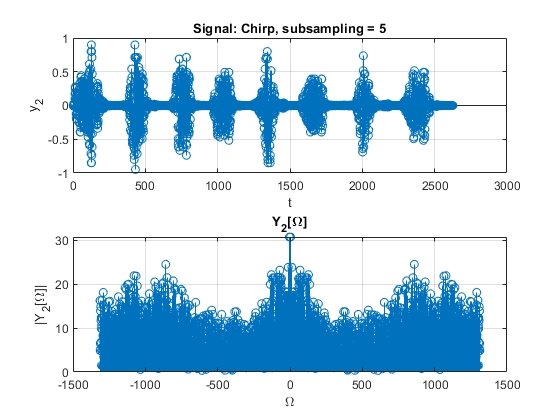


y2 = y(n);
Y2 = fft(y2);

fr = -((N0)/2):((N0-1)/2);

subplot(2,1,1);
stem(y2);
title("Signal: Chirp, subsampling = 5");
ylabel("y_2");
xlabel("t");
grid on;

subplot(2,1,2);
stem(fr, abs(Y2));
title("Y_2[\Omega]");
xlabel("\Omega");
ylabel("|Y_2[\Omega]|");
grid on;

As we increase the subsampling rate, The spectrum gets flatter and flatter. As menioned above as we lower the sampling rate we see that the lower frequency spectral values begin to increase and the higher frequenct values continue to reduce in size.

## Part C

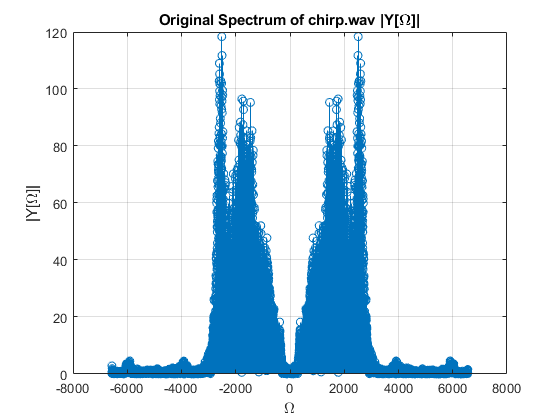

load chirp.mat
filename = 'chirp.wav';
audiowrite(filename, y, Fs);
clear y Fs;

[y, Fs] = audioread('chirp.wav');

N0 = length(y);
T = (2*pi)/N0;
T0 = N0 * T;

Ohm = -N0/2:(N0-1)/2;

Y = fft(y);

subplot(1,1,1);
stem(Ohm, abs(Y));
title("Original Spectrum of chirp.wav |Y[\Omega]|");
xlabel("\Omega");
ylabel("|Y[\Omega]|");
grid on;

### C1

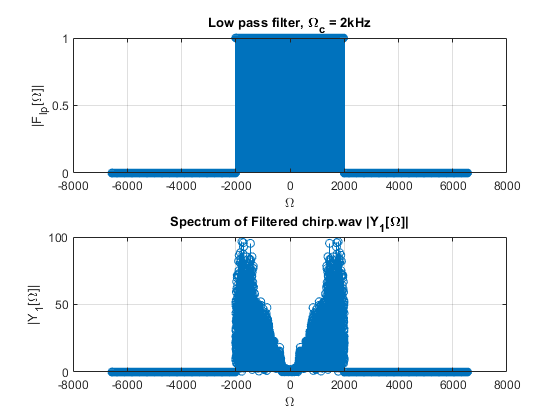

u = @(n) (n>0);
F1 = @(n) u(n + 2000) - u(n-2000);

Ohm = -N0/2:(N0-1)/2;
filter = F1(Ohm);

X1 = Y' .* filter;
x1 = ifft(X1);

subplot(2,1,1);
stem(Ohm, filter);
title("Low pass filter, \Omega_c = 2kHz");
xlabel("\Omega");
ylabel("|F_{lp}[\Omega]|");
grid on;

subplot(2,1,2);
stem(Ohm, abs(X1));
title("Spectrum of Filtered chirp.wav |Y_{1}[\Omega]|");
xlabel("\Omega");
ylabel("|Y_1[\Omega]|");
grid on;

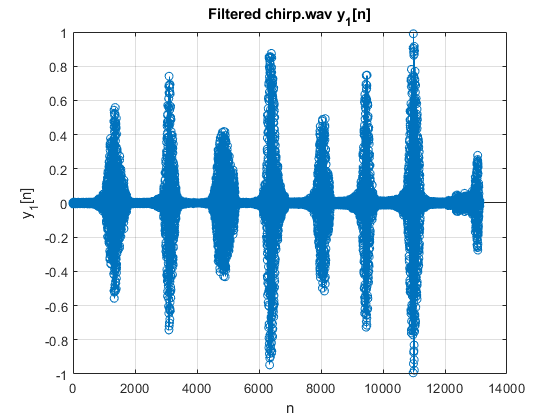

n = 0:N0-1;

subplot(1,1,1);
stem(n, x1);
title("Filtered chirp.wav y_{1}[n]");
xlabel("n");
ylabel("y_1[n]");
grid on;

### C2

The sound has noticebly changes, it's only the audio signal below $f=2kHz$.

### C3

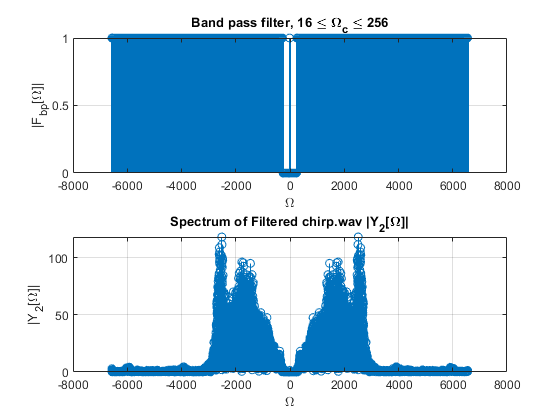

F2 = @(n) 1 - (u(n-16) - u(n-256)) - (u(n+256) - u(n+16)) ;
filter = F2(Ohm);

X2 = Y' .* filter;
x2 = ifft(X2);

subplot(2,1,1);
stem(Ohm, filter);
title("Band pass filter, 16 \leq \Omega_c \leq 256");
xlabel("\Omega");
ylabel("|F_{bp}[\Omega]|");
grid on;


subplot(2,1,2);
stem(Ohm, abs(X2));
title("Spectrum of Filtered chirp.wav |Y_{2}[\Omega]|");
xlabel("\Omega");
ylabel("|Y_2[\Omega]|");
grid on;

It is hard to notice the difference in the sound becuase the signal I choose does not have much bass (Evident in the original spectrum), but you can see a difference in the spectrum.

### C4

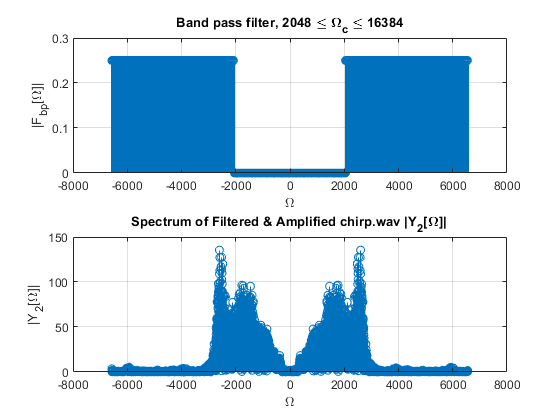

F3 = @(n) (u(n-2048) - u(n-16384)) + (u(n+16384) - u(n+2048));
filter = F3(Ohm).*.25;
X3 = Y' .* filter;

OUT = abs(Y) + X3';

out = ifft(out);

subplot(2,1,1);
stem(Ohm, filter);
title("Band pass filter, 2048 \leq \Omega_c \leq 16384");
xlabel("\Omega");
ylabel("|F_{bp}[\Omega]|");
grid on;


subplot(2,1,2);
stem(Ohm, abs(OUT));
title("Spectrum of Filtered & Amplified chirp.wav |Y_{2}[\Omega]|");
xlabel("\Omega");
ylabel("|Y_2[\Omega]|");
grid on;

Again it is hard to notice because 25% is not alot but it is audible, but it is more evident in the spectrum, the higher frequency components are significantly higher greater than the original.

### C5

We used the linearity property in part 4.